# Extra Credit: Modeling and Simulating a 2D Quadcopter

### Simulink Hover Model:

% load, initiate, and calculate model constants
load Quad2D_constants.mat
b_z = 0.3;
b_y = 0.3;
b_phi = 0.3;
init_z = 3; % m
init_y = 1; % m
init_phi = 0; % rad
net_force = params.m * params.g;
net_torque = 0;
simTime = 5;

% run simulation
out = sim('Quad2DSimulink.slx', 5); % simulate for 5 sec

time = out.z.Time;
z = out.z.Data;
y = out.y.Data;
phi = out.phi.Data;
f = out.f.Data;
tau = out.tau.Data;

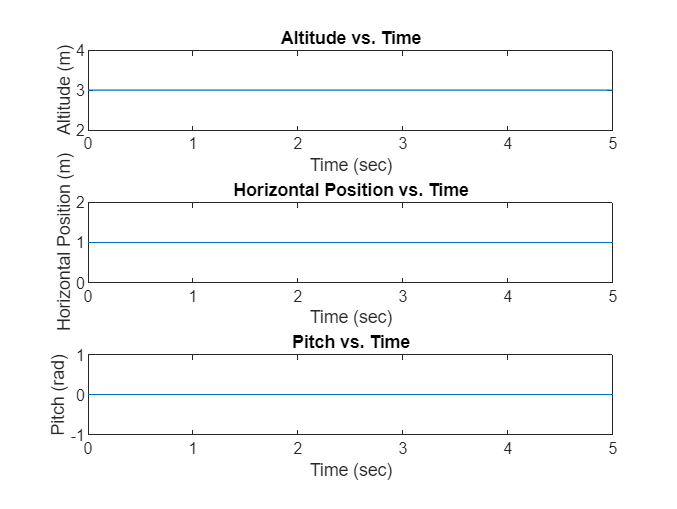

% plot data
subplot(3,1,1)
plot(time, z)
title("Altitude vs. Time")
xlabel("Time (sec)")
ylabel("Altitude (m)")

subplot(3,1,2)
plot(time, y)
title("Horizontal Position vs. Time")
xlabel("Time (sec)")
ylabel("Horizontal Position (m)")

subplot(3,1,3)
plot(time, phi)
title("Pitch vs. Time")
xlabel("Time (sec)")
ylabel("Pitch (rad)")

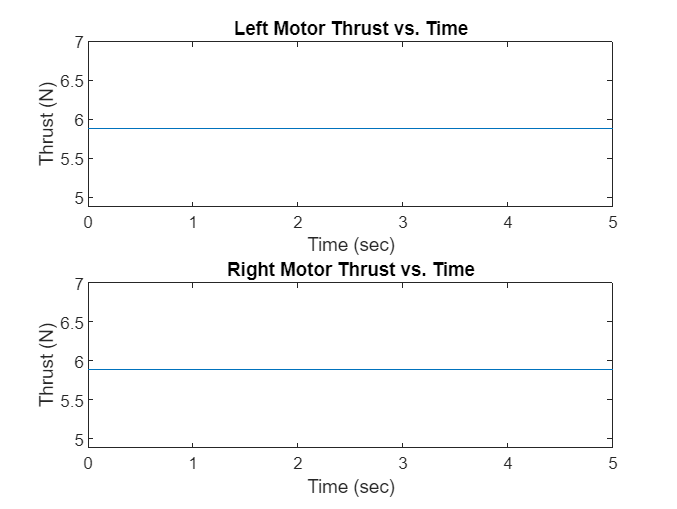

A = [f tau]; % net force and torque data
B = [1 1; -1 1]; % relating to left and right motor thrusts
C = zeros(size(A)); 

for i = 1:length(A) % loop through all data points
     motors = B\A(i,:)'; % calculate motor thrusts
     C(i, 1) = motors(1);
     C(i, 2) = motors(2);
end

left_motor = C(:, 1);
right_motor = C(:, 2);

% plot left and right motor thrusts
subplot(2,1,1)
plot(time, left_motor)
title("Left Motor Thrust vs. Time")
xlabel("Time (sec)")
ylabel("Thrust (N)")

subplot(2,1,2)
plot(time, right_motor)
title("Right Motor Thrust vs. Time")
xlabel("Time (sec)")
ylabel("Thrust (N)")

### Simulink PID Model:

% controller constants and gains
Kp = 12; 
Ki = 7;
Kd = 3;
Kpt = 10;
Kdt = 5;
z_des = 3;
phi_des = 0;
init_z = 0;
init_y = 0;
init_phi = pi/6;

% run simulation
out = sim('Quad2DSimulinkController.slx', 5); % simulate for 5 sec

time = out.z.Time;
z = out.z.Data;
y = out.y.Data;
phi = out.phi.Data;

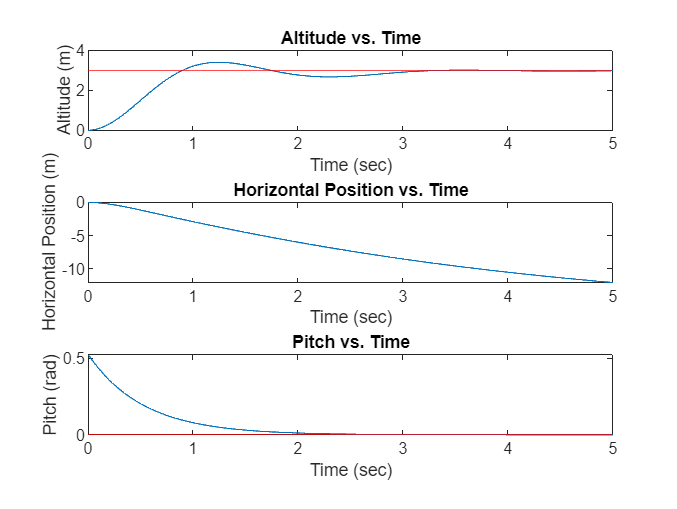

% plot data
subplot(3,1,1)
plot(time, z)
yline(z_des, 'r')
ylim([0 4])
title("Altitude vs. Time")
xlabel("Time (sec)")
ylabel("Altitude (m)")

subplot(3,1,2)
plot(time, y)
title("Horizontal Position vs. Time")
xlabel("Time (sec)")
ylabel("Horizontal Position (m)")

subplot(3,1,3)
plot(time, phi)
yline(phi_des, 'r')
title("Pitch vs. Time")
xlabel("Time (sec)")
ylabel("Pitch (rad)")

### Euler Integration Hover Model:

t0 = 0; % start time
dt = 0.001; % step time
tf = 5; % final time

% Define time vector 
t = [t0:dt:tf];

% Length of time array so we know the number of integration steps to make
N = length(t);

% Create placeholder arrays of zeros for the solution and the first derivative
z = zeros(1,N);
z_dot = zeros(1,N);
y = zeros(1,N);
y_dot = zeros(1,N);
phi = zeros(1,N);
phi_dot = zeros(1,N);

% Set initial conditions
z(1) = 3;
z_dot(1) = 0;
y(1) = 1;
y_dot(1) = 0;
phi(1) = 0;
phi_dot(1) = 0;

% loop through time steps using euler integration
for i = 1:N-1
    z_ddot = (cos(phi(i))/(params.m))*net_force - (b_z/(params.m))*z_dot(i) - params.g;
    z_dot(i+1) = z_dot(i) + z_ddot*dt;
    z(i+1) = z(i) + z_dot(i)*dt;
    
    y_ddot = -(b_y/(params.m))*y_dot(i)-(sin(phi(i))/(params.m))*net_force;
    y_dot(i+1) = y_dot(i) + y_ddot*dt;
    y(i+1) = y(i) + y_dot(i)*dt;

    phi_ddot = net_torque/(params.Ixx) - (b_phi/(params.Ixx))*phi_dot(i);
    phi_dot(i+1) = phi_dot(i) + phi_ddot*dt;
    phi(i+1) = phi(i) + phi_dot(i)*dt;
end

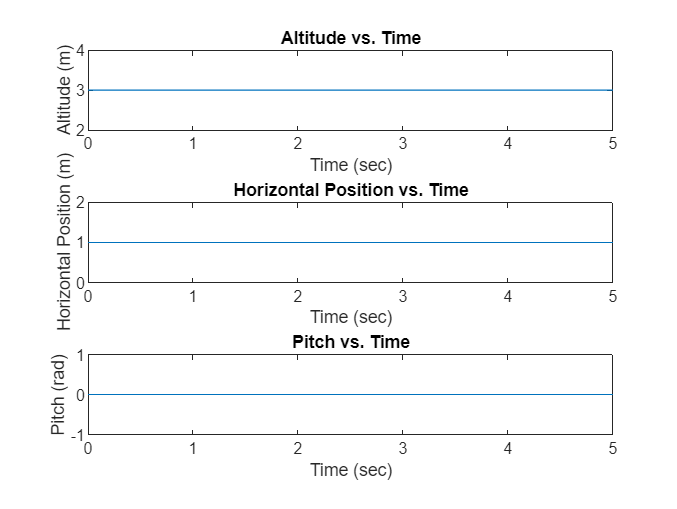

% plot data
subplot(3,1,1)
plot(t, z)
title("Altitude vs. Time")
xlabel("Time (sec)")
ylabel("Altitude (m)")

subplot(3,1,2)
plot(t, y)
title("Horizontal Position vs. Time")
xlabel("Time (sec)")
ylabel("Horizontal Position (m)")

subplot(3,1,3)
plot(t, phi)
title("Pitch vs. Time")
xlabel("Time (sec)")
ylabel("Pitch (rad)")

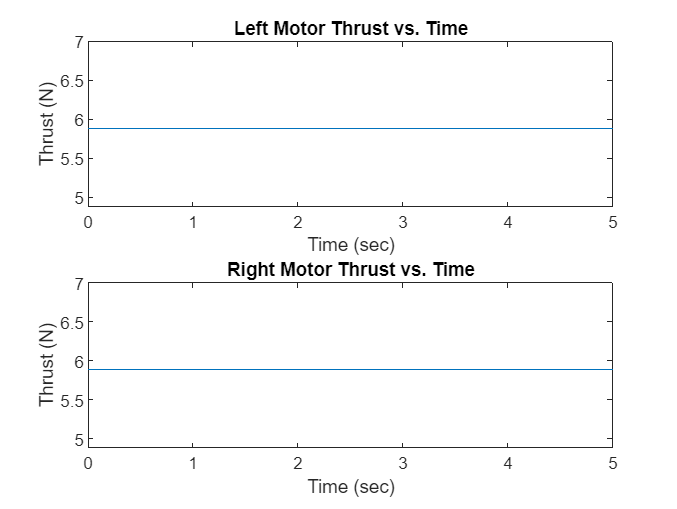

f = zeros(N,1) + net_force;
tau = zeros(N, 1) + net_torque;

A = [f tau]; % net force and torque data
B = [1 1; -1 1]; % relating to left and right motor thrusts
C = zeros(size(A)); 

for i = 1:length(A) % loop through all data points
     motors = B\A(i,:)'; % calculate motor thrusts
     C(i, 1) = motors(1);
     C(i, 2) = motors(2);
end

left_motor = C(:, 1);
right_motor = C(:, 2);

% plot left and right motor thrusts
subplot(2,1,1)
plot(t, left_motor)
title("Left Motor Thrust vs. Time")
xlabel("Time (sec)")
ylabel("Thrust (N)")

subplot(2,1,2)
plot(t, right_motor)
title("Right Motor Thrust vs. Time")
xlabel("Time (sec)")
ylabel("Thrust (N)")

### Euler Integration PID Model:

% Set initial conditions
z(1) = 0;
z_dot(1) = 0;
y(1) = 0;
y_dot(1) = 0;
phi(1) = pi/6;
phi_dot(1) = 0;

% controller constants and gains
Kp = 12; 
Ki = 7;
Kd = 3;
Kpt = 10;
Kdt = 5;
z_des = 3;
phi_des = 0;

% initialize error vectors and constants
z_error = zeros(N, 1);
phi_error = zeros(N,1);
I_z = 0;

% loop through time steps using euler integration
for i = 1:N-1
    % calculate error 
    z_error(i) = z_des - z(i);
    phi_error(i) = phi_des - phi(i);
    
    % PID controller for alititude
    P_z = Kp * z_error(i);
    
    I_z = I_z + Ki * z_error(i) * dt;
    D_z = 0;
    
    if i > 1
        D_z = (Kd * (z_error(i) - z_error(i-1)) / dt);
    end

    net_force = P_z + I_z + D_z;

    % PD controller for orientation
    P_phi = Kpt * phi_error(i);
    D_phi = 0;
    
    if i > 1
        D_phi = (Kdt * (phi_error(i) - phi_error(i-1)) / dt);
    end

    net_torque = P_phi + D_phi;

    z_ddot = (cos(phi(i))/(params.m))*net_force - (b_z/(params.m))*z_dot(i) - params.g;
    z_dot(i+1) = z_dot(i) + z_ddot*dt;
    z(i+1) = z(i) + z_dot(i)*dt;
    
    y_ddot = -(b_y/(params.m))*y_dot(i)-(sin(phi(i))/(params.m))*net_force;
    y_dot(i+1) = y_dot(i) + y_ddot*dt;
    y(i+1) = y(i) + y_dot(i)*dt;
    
    phi_ddot = net_torque/(params.Ixx) - (b_phi/(params.Ixx))*phi_dot(i);
    phi_dot(i+1) = phi_dot(i) + phi_ddot*dt;
    phi(i+1) = phi(i) + phi_dot(i)*dt;
end

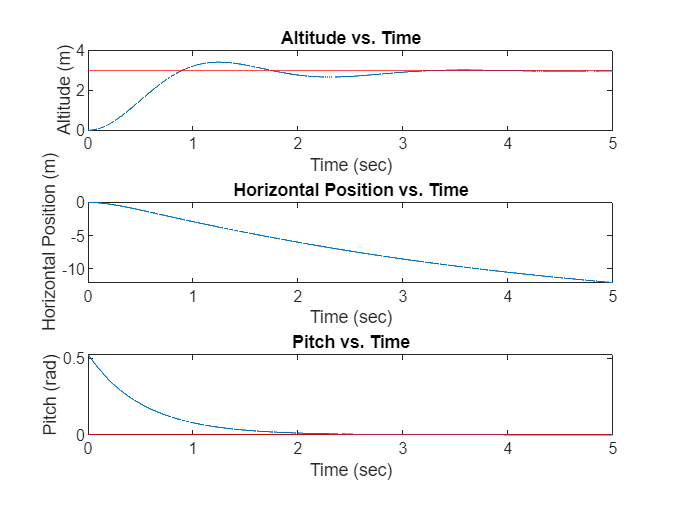

% plot data
subplot(3,1,1)
plot(t, z)
yline(z_des, 'r')
%ylim([0 4])
title("Altitude vs. Time")
xlabel("Time (sec)")
ylabel("Altitude (m)")

subplot(3,1,2)
plot(t, y)
title("Horizontal Position vs. Time")
xlabel("Time (sec)")
ylabel("Horizontal Position (m)")

subplot(3,1,3)
plot(t, phi)
yline(phi_des, 'r')
title("Pitch vs. Time")
xlabel("Time (sec)")
ylabel("Pitch (rad)")